# 1dof free damped

close all
clear all
clc

wn = 5; %Natural frecuency
zeta = [0.05;0.1;0.2]; %Damiping ratios
x0 = 10;
v0 = 60; %Initial Velocity

v0 = 60

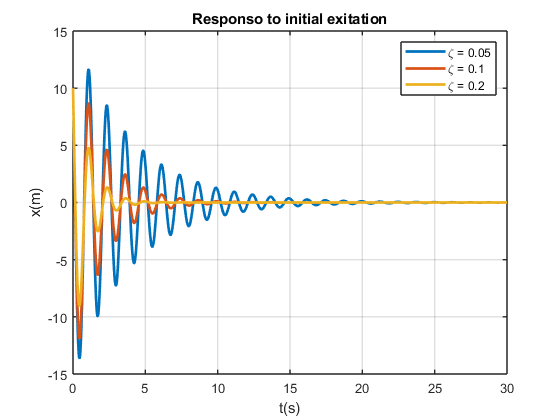

to = 0; %initial time
deltat = 0.01; %time step
tf = 30; %Final time

t = 0:deltat:tf;

for i = 1:length(zeta)
    wd = sqrt(1-zeta(i)^2)*wn; %Damped frecuency
    x = exp(-zeta(i)*wn*t).*(((zeta(i)*wn*x0-v0)/wd)*sin(wd*t) + x0*cos(wd*t));
    plot(t,x,'LineWidth',2,'DisplayName',['\zeta = ',num2str(zeta(i))])
    hold on
end

title('Responso to initial exitation')
grid on
xlabel('t(s)')
ylabel('x(m)')
legend();